## Question 4

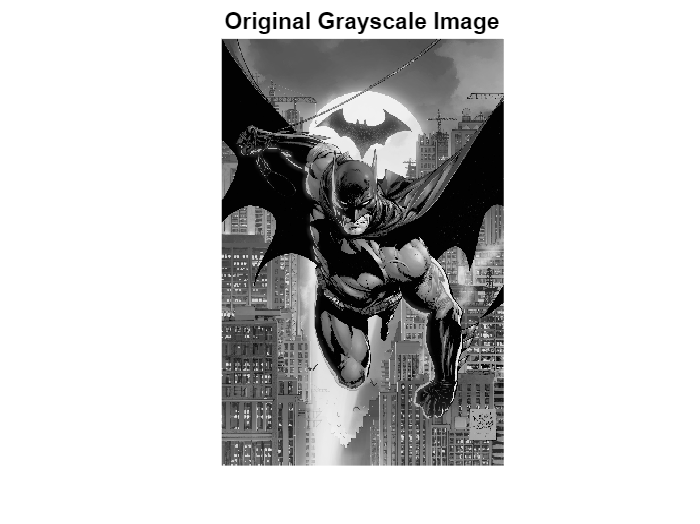

img = imread('Bat.jpg');
gray_img = rgb2gray(img);
figure, imshow(gray_img);
title('Original Grayscale Image');

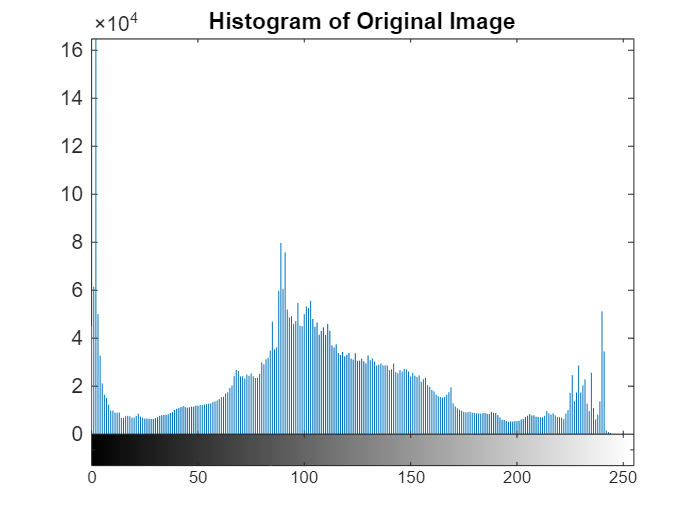

figure;
imhist(gray_img);
title('Histogram of Original Image');

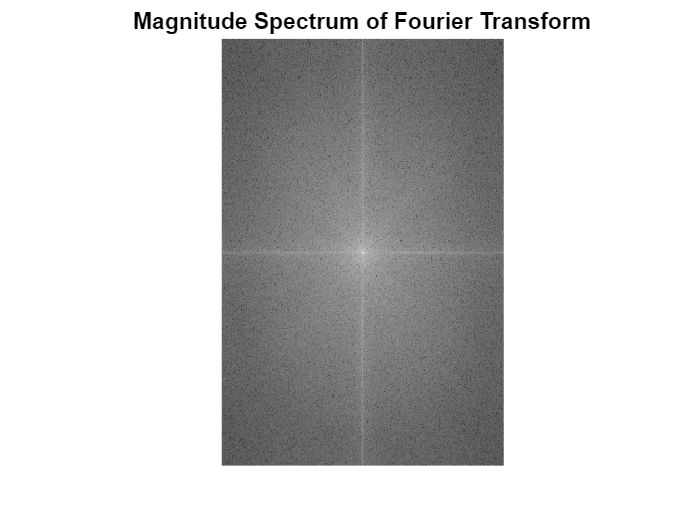

F = fft2(double(gray_img));
F_shifted = fftshift(F);
magnitude_spectrum = log(1+abs(F_shifted));
figure, imshow(magnitude_spectrum, []);
title('Magnitude Spectrum of Fourier Transform');

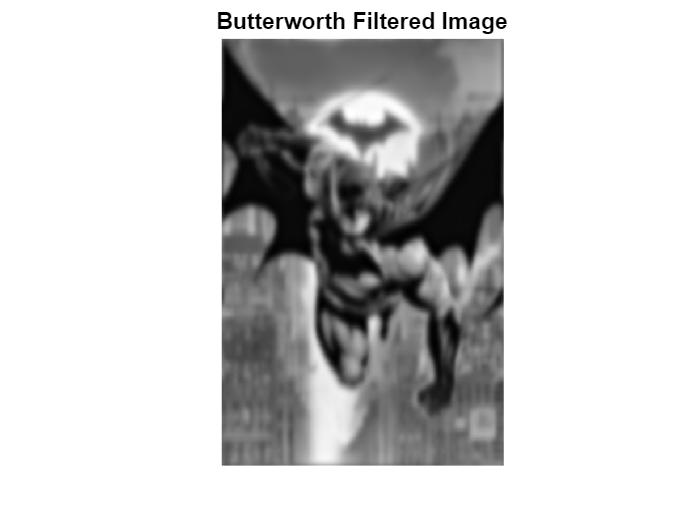

[u, v] = size(gray_img);
[U, V] = meshgrid(-v/2:v/2-1, -u/2:u/2-1);
D = sqrt(U.^2 + V.^2);
D0 = 25; 
n = 2; 
H = 1 ./ (1 + (D / D0).^(2*n)); 
G = H .* F_shifted;
G_shifted = ifftshift(G);
filtered_img_butter = real(ifft2(G_shifted));
figure, imshow(filtered_img_butter, []);
title('Butterworth Filtered Image');

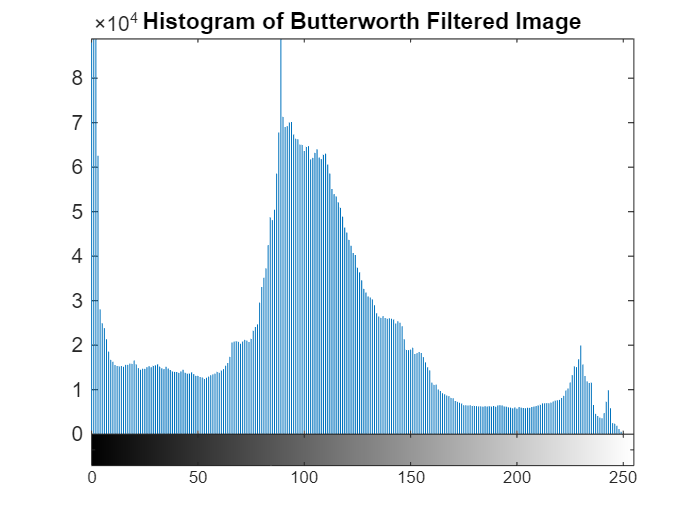

figure, imhist(uint8(filtered_img_butter));
title('Histogram of Butterworth Filtered Image');

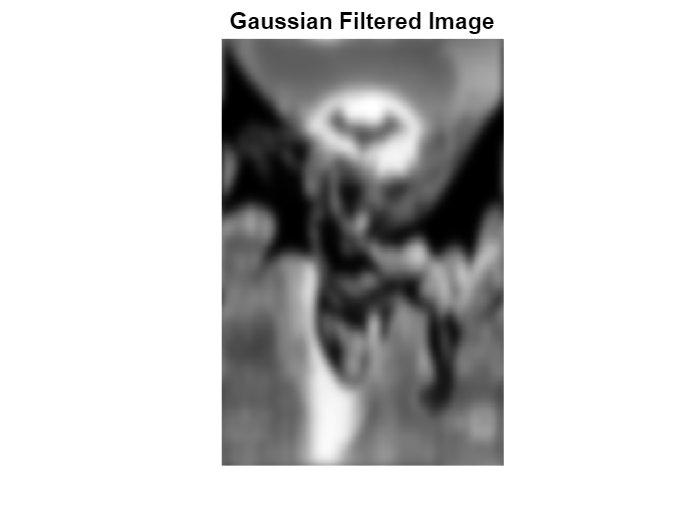

sigma = 10; 
H_gaussian = exp(-(D.^2) / (2*sigma^2));
G_gaussian = H_gaussian .* F_shifted;
G_gaussian_shifted = ifftshift(G_gaussian);
filtered_img_gaussian = real(ifft2(G_gaussian_shifted));
figure, imshow(filtered_img_gaussian, []);
title('Gaussian Filtered Image');

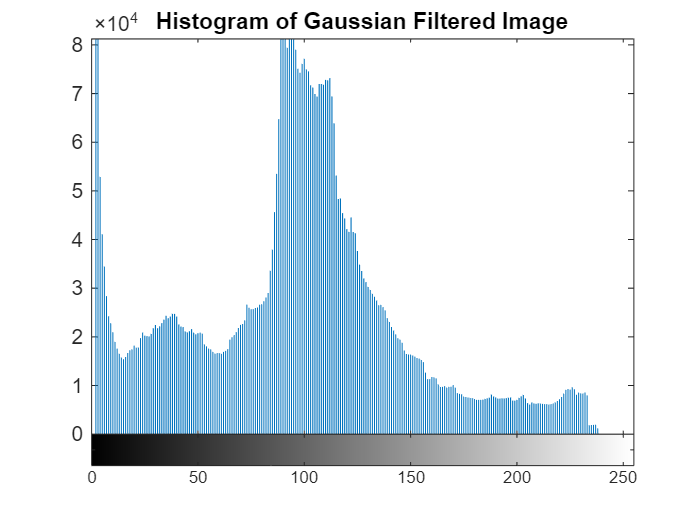

figure, imhist(uint8(filtered_img_gaussian));
title('Histogram of Gaussian Filtered Image');

disp('Explanation of Fourier Transform, Butterworth, and Gaussian Filters:');

Explanation of Fourier Transform, Butterworth, and Gaussian Filters:


disp('Fourier Transform is used to analyze the frequency components of an image. The magnitude spectrum displays the intensity of the frequencies. Areas with high variations, such as edges, correspond to higher values in the spectrum.');

Fourier Transform is used to analyze the frequency components of an image. The magnitude spectrum displays the intensity of the frequencies. Areas with high variations, such as edges, correspond to higher values in the spectrum.


disp('Butterworth filter, a type of low-pass filter, is characterized by its smoothness and lack of ripples in the frequency magnitude response. This smoothness is due to the order of the filter and the cut-off frequency, which controls the transition from passband to stopband.');

Butterworth filter, a type of low-pass filter, is characterized by its smoothness and lack of ripples in the frequency magnitude response. This smoothness is due to the order of the filter and the cut-off frequency, which controls the transition from passband to stopband.


disp('Gaussian filter, also a low-pass filter, uses a Gaussian function for its impulse response. It is highly effective in reducing high-frequency components, thus smoothing the image. The standard deviation of the Gaussian function controls the extent of smoothing.');

Gaussian filter, also a low-pass filter, uses a Gaussian function for its impulse response. It is highly effective in reducing high-frequency components, thus smoothing the image. The standard deviation of the Gaussian function controls the extent of smoothing.


disp('The filters reduce noise and details, with the Butterworth filter providing a smoother transition compared to the sharper transition of the Gaussian filter.');

The filters reduce noise and details, with the Butterworth filter providing a smoother transition compared to the sharper transition of the Gaussian filter.


disp('Comparing the results, the Butterworth filter maintains more of the low-frequency components, while the Gaussian filter attenuates higher frequencies more aggressively.');

Comparing the results, the Butterworth filter maintains more of the low-frequency components, while the Gaussian filter attenuates higher frequencies more aggressively.


disp('Histograms and the MSE (Mean Squared Error) and PSNR (Peak Signal-to-Noise Ratio) metrics help quantify the effects of these filters on the image quality.');

Histograms and the MSE (Mean Squared Error) and PSNR (Peak Signal-to-Noise Ratio) metrics help quantify the effects of these filters on the image quality.


mse_butter = immse(double(gray_img), double(filtered_img_butter));
psnr_butter = psnr(double(filtered_img_butter), double(gray_img));

mse_gaussian = immse(double(gray_img), double(filtered_img_gaussian));
psnr_gaussian = psnr(double(filtered_img_gaussian), double(gray_img));


fprintf('MSE for Butterworth Filtered Image: %f\n', mse_butter);

MSE for Butterworth Filtered Image: 821.065600


fprintf('PSNR for Butterworth Filtered Image: %f dB\n', psnr_butter);

PSNR for Butterworth Filtered Image: -29.143779 dB


fprintf('MSE for Gaussian Filtered Image: %f\n', mse_gaussian);

MSE for Gaussian Filtered Image: 1231.544830


fprintf('PSNR for Gaussian Filtered Image: %f dB\n', psnr_gaussian);

PSNR for Gaussian Filtered Image: -30.904502 dB
